tableN = readtable("si_anode2.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

tablePLFP = readtable("lfp_cathode.csv");
cVecP = table2array(tablePLFP(:,"capacity"));
vVecP = table2array(tablePLFP(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

tableFullLFP = readtable("full_cell_cover2_discharge.csv");
cVecFull = table2array(tableFullLFP(:,"capacity"));
vVecFull = table2array(tableFullLFP(:,"voltage"));

%plot(thetaVecN, vThetaVecN, 'r--', thetaVecP, vThetaVecP, 'b--')
%plot(cVecFull, vVecFull, 'k')

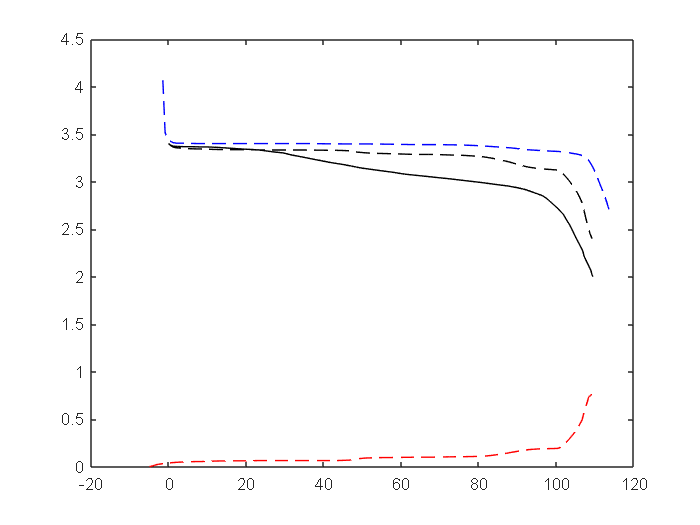

chargeDir = "dchg";
vMax = 3.4;
vMin = 2.4;
cN = 115;
cP = 115;
x0 = 0;
y0 = 0.97;

[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = ...
    combineHalfCells(thetaVecN, vThetaVecN, thetaVecP, vThetaVecP, cN, cP, x0, y0, vMin, vMax, chargeDir);

plot(cVecFullModel, vVecFullModel, 'k--', cVecFull, vVecFull, 'k', ...
    cVecPModel, vVecPModel, 'b--', cVecNModel, vVecNModel, 'r--')

formationLLI = (1-y0)*cN-x0*cN;
fprintf("Formation LLI is %d mAh/g LFP", formationLLI)

Formation LLI is 3.450000e+00 mAh/g LFP